**Student Name:** Naman Shah

**Last 4 Digits of RUID:** 8939

**Section:** C1

**Math 250 MATALB Assignment:** 5

format compact
rand('seed', 8939)

**Question 1**. Norm, Dot Product, and Orthogonal Projection onto a Line

(1)

u = rvect(2)

u =      8
     2


v = rvect(2)

v =      1
     6


rank([u, v])

ans = 2

Yes, the rank is 2.

(1)(a)

The triangle inequality states that ||**u**+**v**|| <= ||**u**|| + ||**v**||, which means that the norm of the sum of the vectors u and v must be less than or equal to the sum of the norm of u with the norm of v.

norm(u)+norm(v)

ans = 14.3290

norm(u+v)

ans = 12.0416

Yes, in this example also, norm(u+v) <= norm(u) + norm(v) holds true.

(1)(b)

The Cauchy-Schwarz inequality states that, for any vectors **u** and **v** in R^n, the absolute value of the dot product of u and v is less than or equal to the dot product of the norms of those two vectors.

| **u . v **| <= ||**u**|| ||**v**||

abs(u'*v)

ans = 20

norm(u)*norm(v)

ans = 50.1597

Yes, abs(u'*v) <= norm(u)*norm(v) holds true.

(1)(c)

w = ((u'*v)/(v'*v))*v

w =     0.5405
    3.2432


z = u - w

z =     7.4595
   -1.2432


z'*v

ans = -8.8818e-16

The dot product of z and v is -8 raised to power -16, so for mathematical purposes we can consider z orthogonal to v.

(1)(d)

P = v*inv(v'*v)*v'

P =     0.0270    0.1622
    0.1622    0.9730


P is a 2x2 matrix because P is the outer product of v to itself, divided by a constant represented by (v*v)^-1. Since v is a 2x1 matrix, the product of v by its tranpose will be a square matrix of nxn, where n is the number of rows in v, which is equivalent to the number of columns in v's transpose.

P*u

ans =     0.5405
    3.2432


w

w =     0.5405
    3.2432


Yes, Pu = w.

**Question 2**.  Gram-Schmidt Orthogonalization and QR Factorization

u1 = rvect(3)

u1 =      5
     8
     6


u2 =  rvect(3)

u2 =      9
     7
     6


u3 = rvect(3)

u3 =      6
     4
     4


rank([u1, u2, u3])

ans = 3

The rank is 3.

(2)(a)

r =  0:0.05:1; hold on
plot3(r*u1(1),r*u1(2),r*u1(3), 'r:')
plot3(r*u2(1),r*u2(2),r*u2(3), 'g:')
plot3(r*u3(1),r*u3(2),r*u3(3), 'b:')

v1 = u1

v1 =      5
     8
     6


v2 = u2 - ((u2'*v1)/(abs(v1'*v1)))*v1

v2 =     3.5200
   -1.7680
   -0.5760


v3 = u3 - ((u3'*v1)/(abs(v1'*v1)))*v1 - ((u3'*v2)/(abs(v2'*v2)))*v2

v3 =    -0.0485
   -0.1938
    0.2988


P1 = v1*inv(v1'*v1)*v1', v2 = u2 - P1*u2

P1 =     0.2000    0.3200    0.2400
    0.3200    0.5120    0.3840
    0.2400    0.3840    0.2880


v2 =     3.5200
   -1.7680
   -0.5760


v1'*v2

ans = -1.0658e-14

Yes, v1 and v2 are mutually orthogonal.

plot3(r*v2(1),r*v2(2),r*v2(3), 'g-.')
P2 = v2*inv(v2'*v2)*v2', v3 = u3 - P1*u3 - P2*u3

P2 =     0.7818   -0.3927   -0.1279
   -0.3927    0.1972    0.0643
   -0.1279    0.0643    0.0209


v3 =    -0.0485
   -0.1938
    0.2988


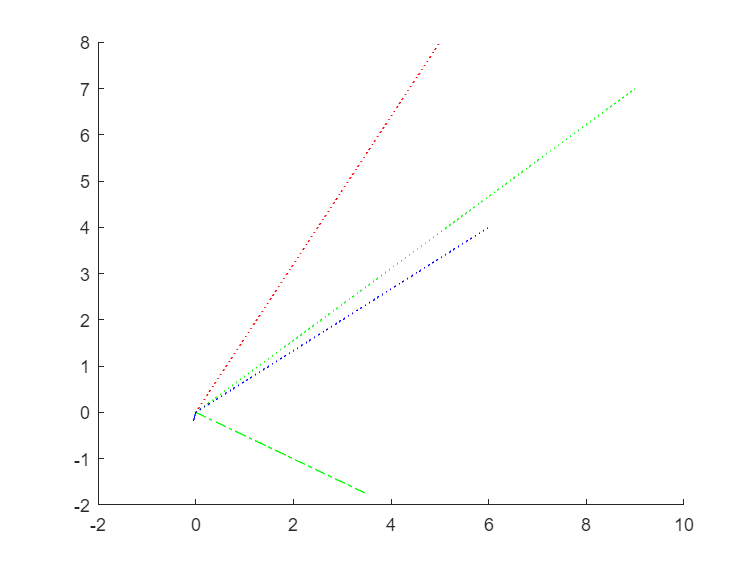

plot3(r*v3(1),r*v3(2),r*v3(3), 'b-.')

v1'*v3

ans = 5.3291e-15

v2'*v3

ans = 2.8033e-15

Yes, v1, v2 and v3 are all mutually orthogonal.

(2)(c)

w1 = v1/norm(v1)

w1 =     0.4472
    0.7155
    0.5367


w2 = v2/norm(v2)

w2 =     0.8842
   -0.4441
   -0.1447


w3 = v3/norm(v3)

w3 =    -0.1348
   -0.5392
    0.8313


Q = [w1, w2, w3]

Q =     0.4472    0.8842   -0.1348
    0.7155   -0.4441   -0.5392
    0.5367   -0.1447    0.8313


(2)(c)(i)

The entires in Q^T Q will be the dot products of the orthonormal vectors of w1, w2, and w3, with each other and themselves. Because each entry would be a dot product of wi and wj, which are orthonormal. But, if wi = wj, then the dot product of these would be ones, as again, the vectors are normal vectors. So, Q^T Q might be the Identity Matrix.

transpose(Q)*Q

ans =     1.0000   -0.0000    0.0000
   -0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


Yes, our assumption was correct.

(2)(c)(ii)

The inverse matrix Q^-1 is equal to Q^T. If Q is an orthogonal matrix, then its inverse must be equal to its transpose.

transpose(Q)

ans =     0.4472    0.7155    0.5367
    0.8842   -0.4441   -0.1447
   -0.1348   -0.5392    0.8313


inv(Q)

ans =     0.4472    0.7155    0.5367
    0.8842   -0.4441   -0.1447
   -0.1348   -0.5392    0.8313


Yes, both the inverse of Q and the transpose of Q are the same.

(2)(d)

A = [u1, u2, u3]

A =      5     9     6
     8     7     4
     6     6     4


R = Q'*A

R =    11.1803   12.2537    7.6921
   -0.0000    3.9810    2.9500
    0.0000    0.0000    0.3595


A

A =      5     9     6
     8     7     4
     6     6     4


Q*R

ans =     5.0000    9.0000    6.0000
    8.0000    7.0000    4.0000
    6.0000    6.0000    4.0000


Yes, A is equal to QR.

(2)(d)(iii)

Let R have entries rij. We know w2.u1 = w3.u2 = w3.u1 = 0. 

Using these 3 equations, we know that r21 = 0 because we find that using w2.u1, which is zero as they are orthogonal to each other. Similarly, r31 and r32 are also equal to zero, since w3.u1 and w3.u2 are also zero. So, for any rij, if wi.uj = 0, the entry at R would also be zero, making R an upper triangular matrix.

R is upper triangular also because each entry is the dot product of corresponding the columns of matrix A and the orthnormal columns of matrix Q. Thus we see that R is upper triangular because by definition, a 3x3 matrix is upper triangular if the (2,1), (3,1), and (3,2) entries are zero. 

**Question 3**.  Orthogonal Projection onto a Subspace

a1 = rvect(5)

a1 =      7
     0
     4
     1
     9


a2 = rvect(5)

a2 =      5
     9
     3
     7
     8


a3 = rvect(5)

a3 =      8
     0
     2
     0
     7


A = [a1, a2, a3]

A =      7     5     8
     0     9     0
     4     3     2
     1     7     0
     9     8     7


rank(A)

ans = 3

Yes, they are linearly independent.

(3)(a)

W = colspace(sym(A))

$$W = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ -\frac{1}{9} & \frac{56}{81} & \frac{4}{9}\\ \frac{5}{9} & \frac{25}{162} & \frac{23}{18} \end{array}\right)$$

Q = grams(A)

Q =     0.5774   -0.0913    0.7222
         0    0.8216    0.1960
    0.3299   -0.0391   -0.5641
    0.0825    0.5608   -0.1955
    0.7423    0.0261   -0.2893


w1 = Q(:,1)

w1 =     0.5774
         0
    0.3299
    0.0825
    0.7423


w2 = Q(:,2)

w2 =    -0.0913
    0.8216
   -0.0391
    0.5608
    0.0261


w3 = Q(:,3)

w3 =     0.7222
    0.1960
   -0.5641
   -0.1955
   -0.2893


Q'*Q

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


We get an identity matrix, because when we multiply any wi into wj when they are not equal, wi and wj are orthonormal to each other, making the entry zero. Also, when you find the dot product of a normal vector with itself, you get a one.

(3)(b)

P = w1*w1' + w2*w2' + w3*w3'

P =     0.8632    0.0665   -0.2133   -0.1447    0.2173
    0.0665    0.7134   -0.1427    0.4224   -0.0353
   -0.2133   -0.1427    0.4285    0.1155    0.4071
   -0.1447    0.4224    0.1155    0.3595    0.1324
    0.2173   -0.0353    0.4071    0.1324    0.6354


v = rvect(5)

v =      6
     3
     5
     5
     2


w = P*v

w =     4.0233
    3.8675
    1.8265
    3.0386
    5.1658


z = v-w

z =     1.9767
   -0.8675
    3.1735
    1.9614
   -3.1658


P*w

ans =     4.0233
    3.8675
    1.8265
    3.0386
    5.1658


w

w =     4.0233
    3.8675
    1.8265
    3.0386
    5.1658


P*z

ans = 1.0e-15 *

   -0.8882
   -0.3747
    0.4441
    0.0555
         0


norm(P*z)

ans = 1.0628e-15

Yes, Pw =  w, and Pz is very close to zero, for this problem we will count it to be zero.

We know now that w is in the subspace W and z is the component of v perpendicular to W

(3)(c)

PW = A*inv(A'*A)*A'

PW =     0.8632    0.0665   -0.2133   -0.1447    0.2173
    0.0665    0.7134   -0.1427    0.4224   -0.0353
   -0.2133   -0.1427    0.4285    0.1155    0.4071
   -0.1447    0.4224    0.1155    0.3595    0.1324
    0.2173   -0.0353    0.4071    0.1324    0.6354


norm(PW-P)

ans = 1.4036e-15

Yes, PW-P = 0.